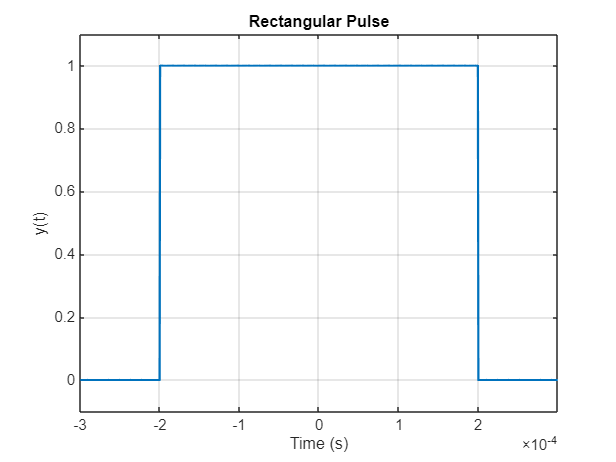

clear
clc
close all

% Time axis
x = linspace(-3e-4, 3e-4, 1000);

% Pulse width parameter
tau = 2e-4;

% Rectangular pulse
y = heaviside(x + tau) - heaviside(x - tau);

% Plot
plot(x, y, 'LineWidth', 1.5)

grid on
xlabel('Time (s)')
ylabel('y(t)')
title('Rectangular Pulse')

xlim([-3e-4 3e-4])
ylim([-0.1 1.1])

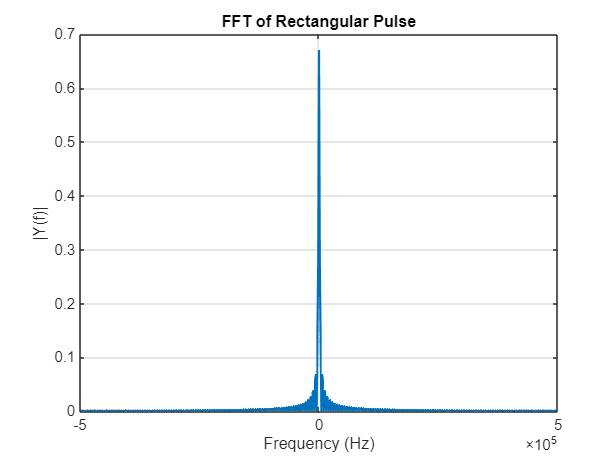


Fs = 1e6;
Ts = 1/Fs;

t = -3e-4:Ts:3e-4-Ts;

% Rectangular pulse
y = heaviside(t + 2e-4) - heaviside(t - 2e-4);

% Number of samples
N = length(y);

% FFT
Y = fftshift(fft(y));

% Frequency axis
f = (-N/2:N/2-1)*(Fs/N);

% Magnitude
y_magnitude = abs(Y)/N;

% Plot
plot(f, y_magnitude, 'LineWidth', 1.5)
grid on
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')
title('FFT of Rectangular Pulse')

%xlim([-10000 10000])